# Call Python from MATLAB to Compare PyTorch Models for Image Classification

## Overview

This example shows how to call Python® from MATLAB® to compare PyTorch® image classification models, and then import the fastest PyTorch model into MATLAB.

Preprocess an image in MATLAB, find the fastest PyTorch model with co-execution, and then import the model into MATLAB for deep learning workflows that Deep Learning Toolbox™ supports. For example, take advantage of MATLAB's easy-to-use low-code apps for visualizing, analyzing, and modifying deep neural networks, or deploy the imported network.

This example shows the co-execution workflow between PyTorch and Deep Learning Toolbox. You can use the same workflow for co-execution with TensorFlow™.

## Python Environment

Set up the Python environment by first running commands at your Mac OS terminal and then, set up the Python interpreter in MATLAB.

Go to your working folder. Set up and activate the Python virtual environment `env` in your working folder.

  Install the necessary Python libraries for this example. Check the installed versions of the libraries.

For reference, this example is run with:

- Python 3.10.8

- numpy 1.23.4

- torch 1.13.0

- torchvision 1.13.0

Set up the Python interpreter for MATLAB.

pe = pyenv(ExecutionMode="OutOfProcess",Version="./env/bin/python3.10")

pe =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env/bin/python3.10"
          Library: "/Library/Frameworks/Python.framework/Versions/3.10/lib/libpython3.10.dylib"
             Home: "/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


## PyTorch Models

Get three pretrained PyTorch models (VGG, MobileNet v2, and MNASNet) from the torchvision library. For more information, see [TORCHVISION.MODELS](https://pytorch.org/vision/0.8/models.html).

You can access Python libraries directly from MATLAB by adding the `py.` prefix to the Python name. For more information on how to access Python libraries, see [Access Python Modules from MATLAB - Getting Started](https://www.mathworks.com/help/matlab/matlab_external/create-object-from-python-class.html).

model1 = py.torchvision.models.vgg16(pretrained=true);

/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env/lib/python3.10/site-packages/torchvision/models/_utils.py:208: UserWarning: The parameter 'pretrained' is deprecated since 0.13 and may be removed in the future, please use 'weights' instead.
  warnings.warn(
/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env/lib/python3.10/site-packages/torchvision/models/_utils.py:223: UserWarning: Arguments other than a weight enum or `None` for 'weights' are deprecated since 0.13 and may be removed in the future. The current behavior is equivalent to passing `weights=VGG16_Weights.IMAGENET1K_V1`. You can also use `weights=VGG16_Weights.DEFAULT` to get the most up-to-date weights.
  warnings.warn(msg)


model2 = py.torchvision.models.mobilenet_v2(pretrained=true);

/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env/lib/python3.10/site-packages/torchvision/models/_utils.py:223: UserWarning: Arguments other than a weight enum or `None` for 'weights' are deprecated since 0.13 and may be removed in the future. The current behavior is equivalent to passing `weights=MobileNet_V2_Weights.IMAGENET1K_V1`. You can also use `weights=MobileNet_V2_Weights.DEFAULT` to get the most up-to-date weights.
  warnings.warn(msg)


model3 = py.torchvision.models.mnasnet1_0(pretrained=true);

/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env/lib/python3.10/site-packages/torchvision/models/_utils.py:223: UserWarning: Arguments other than a weight enum or `None` for 'weights' are deprecated since 0.13 and may be removed in the future. The current behavior is equivalent to passing `weights=MNASNet1_0_Weights.IMAGENET1K_V1`. You can also use `weights=MNASNet1_0_Weights.DEFAULT` to get the most up-to-date weights.
  warnings.warn(msg)


## Preprocess Image

Read the image you want to classify. Show the image.

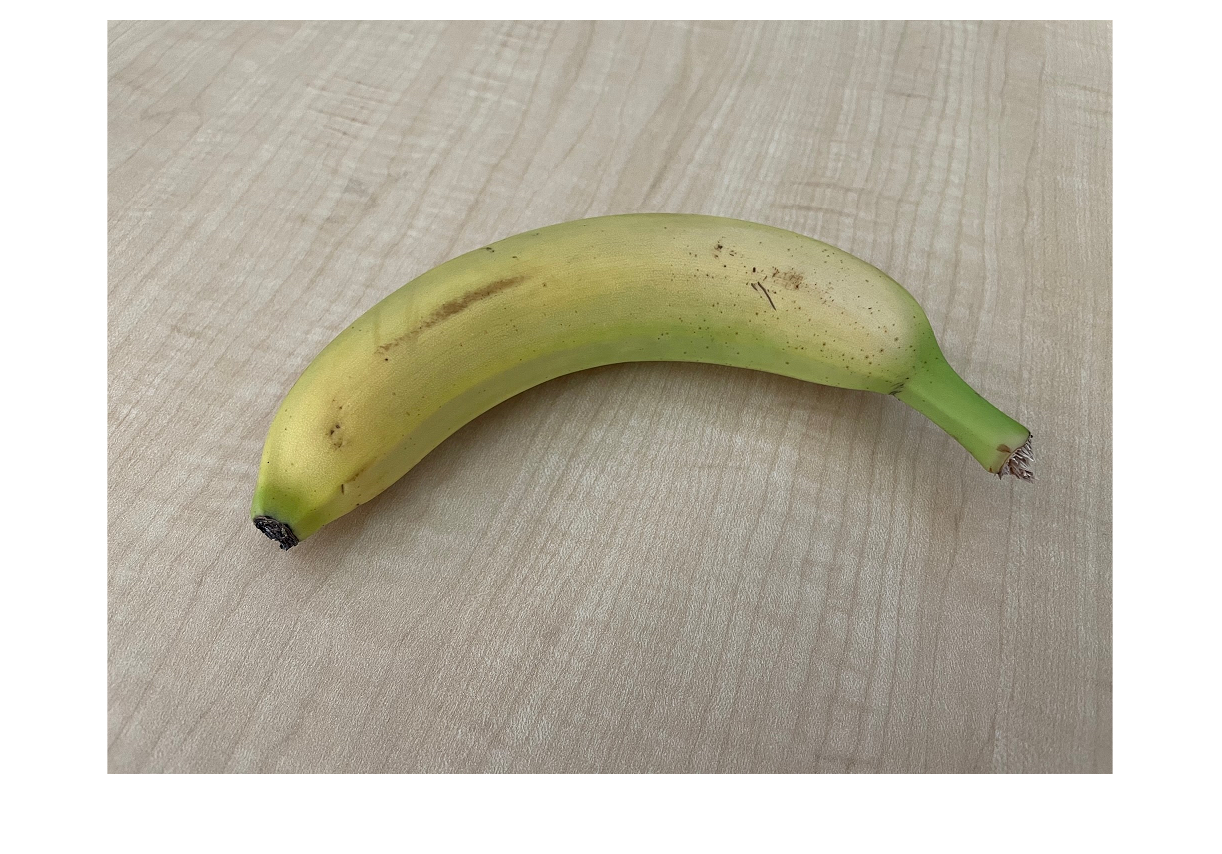

imgOriginal = imread("banana.png");
imshow(imgOriginal)

Resize the image to the input size of the network.

InputSize = [224 224 3];
img = imresize(imgOriginal,InputSize(1:2));

You must preprocess the image in the same way as the training data. For more information, see [Input Data Preprocessing](https://www.mathworks.com/help/deeplearning/ug/tips-on-importing-models-from-tensorflow-pytorch-and-onnx.html#mw_7d593336-5595-49a0-9bc0-184ba6cebb80). Rescale the image. Then, normalize the image by subtracting the training images mean and dividing by the training images standard deviation. 

imgProcessed = rescale(img,0,1);

meanIm = [0.485 0.456 0.406];
stdIm = [0.229 0.224 0.225];
imgProcessed = (imgProcessed - reshape(meanIm,[1 1 3]))./reshape(stdIm,[1 1 3]);

Permute the image data from the Deep Learning Toolbox dimension ordering (HWCN) to the PyTorch dimension ordering (NCHW). For more information on input dimension data ordering for different deep learning platforms, see [Input Dimension Ordering](https://www.mathworks.com/help/deeplearning/ug/tips-on-importing-models-from-tensorflow-pytorch-and-onnx.html#mw_ca5d4cba-9c12-4f01-8fe1-6329730c92b2).

imgForTorch = permute(imgProcessed,[4 3 1 2]);

## Classify Image with Co-Execution

Check that the PyTorch models work as expected by classifying an image. Call Python from MATLAB to predict the label.

Get the class names from `squeezenet`, which is also trained with ImageNet images (same as the torchvision models).

squeezeNet = squeezenet;
ClassNames = squeezeNet.Layers(end).Classes;

Convert the image to a tensor in order to classify the image with a PyTorch model.

X = py.numpy.asarray(imgForTorch);
X_torch = py.torch.from_numpy(X).float();

sys:1: UserWarning: The given NumPy array is not writable, and PyTorch does not support non-writable tensors. This means writing to this tensor will result in undefined behavior. You may want to copy the array to protect its data or make it writable before converting it to a tensor. This type of warning will be suppressed for the rest of this program. (Triggered internally at /Users/runner/work/pytorch/pytorch/pytorch/torch/csrc/utils/tensor_numpy.cpp:205.)


Classify the image with co-execution using the MNASNet model. The model predicts the correct label.

y_val = model1(X_torch);

predicted = py.torch.argmax(y_val);
label = ClassNames(double(predicted.tolist)+1)

label = categorical
     banana 


## Compare PyTorch Models

Find the fastest PyTorch model by calling Python from MATLAB. Predict the image classification label multiple times for each of the PyTorch models.

N = 30;

for i = 1:N
    tic
    model1(X_torch);
    T(i) = toc;
end
mean(T)

ans = 0.5947

for i = 1:N
    tic
    model2(X_torch);
    T(i) = toc;
end
mean(T)

ans = 0.1400

for i = 1:N
    tic
    model3(X_torch);
    T(i) = toc;
end
mean(T)

ans = 0.1096

This simple test shows that the fastest model in predicting is MNASNet. You can run different tests on PyTorch models easily and fast with co-execution to find the model that best suits your application and workflow.

## Save PyTorch Model

You can execute Python statements in the Python interpreter directly from MATLAB by using the [`pyrun`](https://www.mathworks.com/help/matlab/ref/pyrun.html) function. The pyrun function is a stateful interface between MATLAB and Python that saves the state between the two platforms.

Save the fastest PyTorch model, among the three models compared. Then, trace the model. For more information on how to trace a PyTorch model, see [Torch documentation: Tracing a function](https://pytorch.org/docs/stable/generated/torch.jit.trace.html).

pyrun("import torch;X_rnd = torch.rand(1,3,224,224)")
pyrun("traced_model = torch.jit.trace(model3.forward,X_rnd)",model3=model3)

/Users/sivylla/OneDrive - MathWorks/Documents/PMM_AI/BlogPosts/CoExecution_fromMATLAB/GitLab/env/lib/python3.10/site-packages/torch/jit/_trace.py:1001: TracerWarning: Output nr 1. of the traced function does not match the corresponding output of the Python function. Detailed error:
Tensor-likes are not close!

Mismatched elements: 1000 / 1000 (100.0%)
Greatest absolute difference: 3.103491894900799 at index (0, 902) (up to 1e-05 allowed)
Greatest relative difference: 550.5045082674775 at index (0, 437) (up to 1e-05 allowed)
  _check_trace(


pyrun("traced_model.save('traced_mnasnet1_0.pt')")

## Import PyTorch Model

Import the MNASNet model by using the [`importNetworkFromPyTorch`](https://www.mathworks.com/help/deeplearning/ref/importnetworkfrompytorch.html) function. The function imports the model as an uninitialized `dlnetwork` object.

net = importNetworkFromPyTorch("traced_mnasnet1_0.pt")

net =   dlnetwork with properties:

         Layers: [152×1 nnet.cnn.layer.Layer]
    Connections: [163×2 table]
     Learnables: [210×3 table]
          State: [104×3 table]
     InputNames: {'TopLevelModule_layers_0'}
    OutputNames: {'aten__linear12'}
    Initialized: 0

  View summary with summary.


Create an image input layer. Then, add the image input layer to the imported network and initialize the network by using the [`addInputLayer`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.addinputlayer.html) function.

inputLayer = imageInputLayer(InputSize,Normalization="none");
net = addInputLayer(net,inputLayer,Initialize=true);

Analyze the imported network. Observe that there are no warning or errors, which means that the network is ready to use.

analyzeNetwork(net)

## Classify Image in MATLAB

Convert the image to a [`dlarray`](https://www.mathworks.com/help/deeplearning/ref/dlarray.html) object. Format the image with dimensions "SSCB" (spatial, spatial, channel, batch).

Img_dlarray = dlarray(single(imgProcessed),"SSCB");

Classify the image and find the predicted label.

prob = predict(net,Img_dlarray);
[~,label_ind] = max(prob);

Show the image with the classification label.

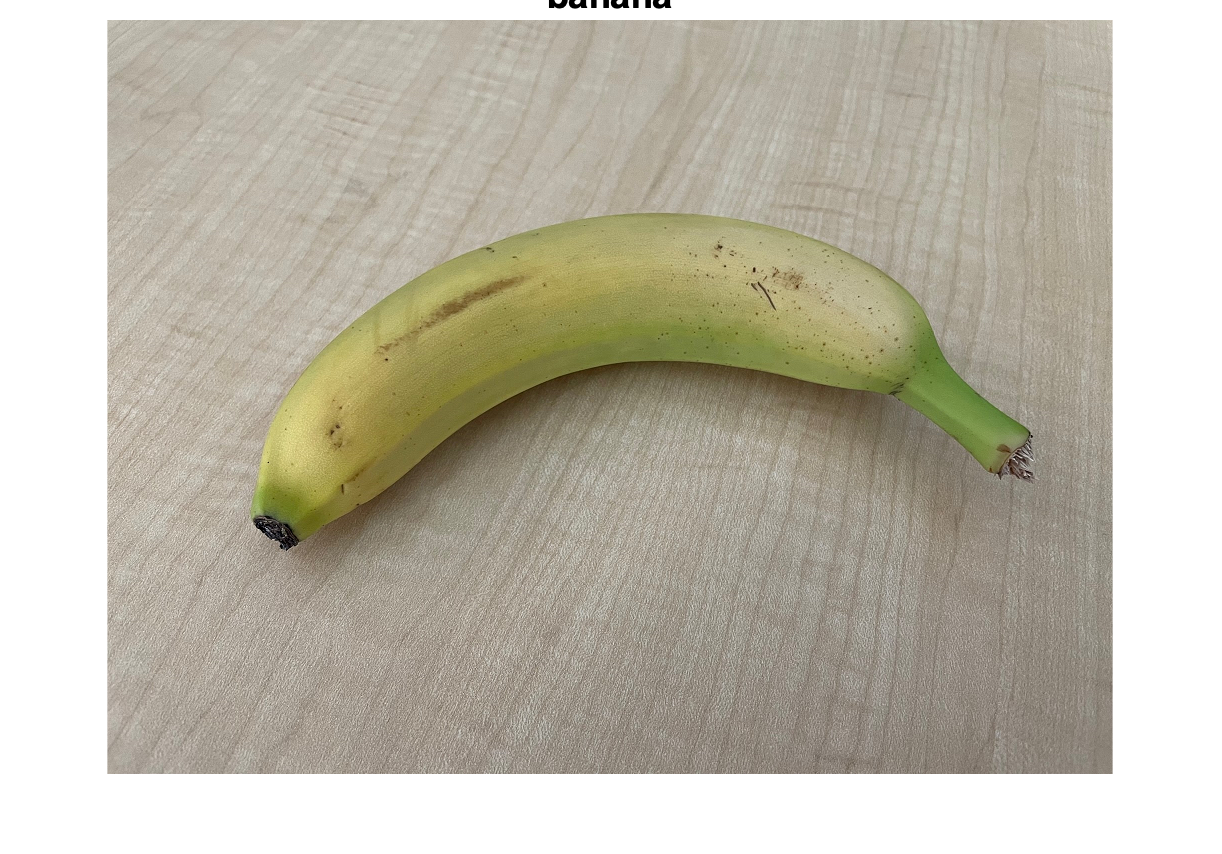

imshow(imgOriginal)
title(ClassNames(label_ind),FontSize=18)